freq_dist = 2.^(1:14);
primes = list_prime(2,20000);
[~, idx] = min(abs(freq_dist' - primes), [], 2); 
freq_array = [0.3, 0.7, primes(idx)];
freq_array = freq_array(1:end-1);
amp = 0.1;
Fs = 40000;
period = 1/min(freq_array);
n_period = 1;

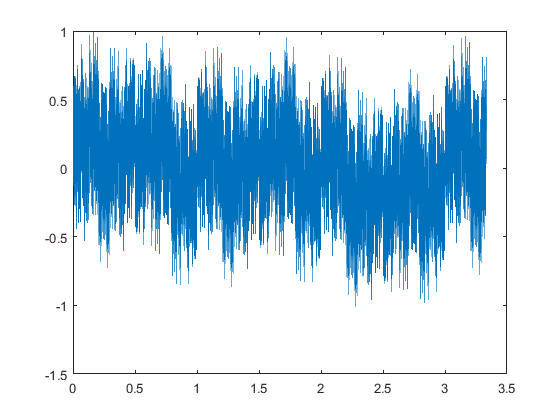

[t, y] = draw_multisine_(freq_array,[],amp,Fs,period,n_period);
plot(t,y)

peak2rms(y)

ans = 3.6673

max(y, [], 2)

ans = 0.9896

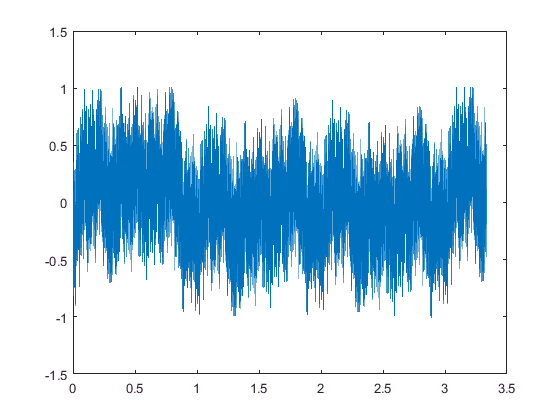

[t, y] = draw_multisine_(freq_array,x,amp,Fs,period,n_period);
plot(t,y)

peak2rms(y)

ans = 3.5029

max(y)

ans = 1.0092

objective = @(x)simple_fitness(x, freq_array, amp, Fs, period, n_period);
nvars = length(freq_array);
lb = zeros(1, nvars);
ub = zeros(1, nvars) + pi*2;
opts = optimoptions(@ga,'PlotFcn',{@gaplotbestf,@gaplotstopping});
opts = optimoptions(opts,'UseVectorized',true);

n = 10;
err = zeros(n,1);
pred = zeros(n, length(freq_array));
for i = 1:n
    [x,fval] = ga(objective, nvars, [], [], [], [], lb, ub,[], opts);
    pred(i, :) = x;
    err(i, 1) = fval;
end

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


function err  = simple_fitness( x, freq_array, amp, Fs, period, n_period )

%opt = stepDataOptions('InputOffset',0, 'StepAmplitude',1);

[~, y] = draw_multisine_(freq_array,x,amp,Fs,period,n_period);
err = reshape(peak2rms(y, 2), [], 1);
end

function primes = list_prime(start, finish)
    
n = start : finish;
p = isprime(n);
primes = n(p); 
end